# Read Messages from ROS 2 Bag Log File

Create a `ros2bagreader` object that contains all the messages in the log file. 

bagReader = rosbagreader('jackal_sim.bag')

bagReader =   rosbagreader with properties:

           FilePath: 'C:\MATLAB\matlab-ros-ims\2_ReadRosBags\jackal_sim.bag'
          StartTime: 1.5247e+09
            EndTime: 1.5247e+09
        NumMessages: 27033
    AvailableTopics: [4×3 table]
    AvailableFrames: {15×1 cell}
        MessageList: [27033×4 table]


Get all the messages in the `ros2bagreader` object.

% msgs = readMessages(bagReader); % Depending on the size can take long

Select a subset of the messages, filtered by topic and time.

bagSel = select(bagReader,"Topic","/odometry/filtered", ...
    "Time",[bagReader.StartTime,bagReader.StartTime+10])

bagSel =   rosbagreader with properties:

           FilePath: 'C:\MATLAB\matlab-ros-ims\2_ReadRosBags\jackal_sim.bag'
          StartTime: 1.5247e+09
            EndTime: 1.5247e+09
        NumMessages: 500
    AvailableTopics: [1×3 table]
    AvailableFrames: {15×1 cell}
        MessageList: [500×4 table]


Get the messages in the selection.

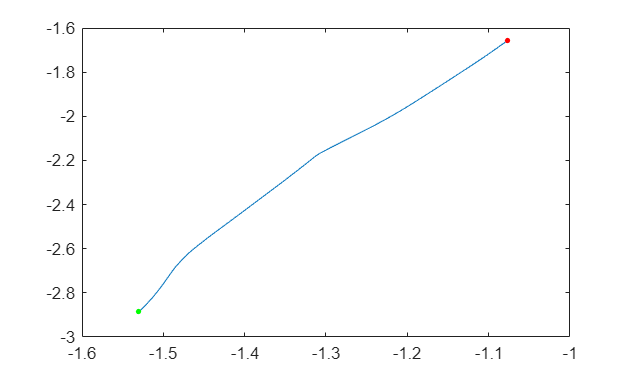

msgsFiltered = readMessages(bagSel,"DataFormat","struct");
xPoints = cellfun(@(m) double(m.Pose.Pose.Position.X),msgsFiltered);
yPoints = cellfun(@(m) double(m.Pose.Pose.Position.Y),msgsFiltered);
plot(xPoints,yPoints)
hold on
scatter(xPoints(1),yPoints(1),10,"red","filled")
scatter(xPoints(end),yPoints(end),10,"green","filled")
hold off

### **Lidar Scan**

Now read and plot the lidar scan messages

% bagSel = select(bagReader,"Topic",...)

### SLAM

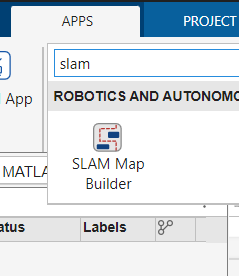

*Copyright 2020 The MathWorks, Inc.*